# DSP Take-Home Test

Samuel Stark (sws35)

November 2021

## Question 1

Consider the following discrete systems (not pictured):

List which of these are 

**a) Linear**

B, E, F, G are linear.

A includes absolute-value => non linear.

C:$\begin{array}{l}
T\left\lbrace {\mathrm{az}}_n +{\mathrm{bu}}_n \right\rbrace =\frac{3\left({\mathrm{az}}_{n-1} +{\mathrm{bu}}_{n-1} \right)+\left({\mathrm{az}}_{n-2} +{\mathrm{bu}}_{n-2} \right)}{{\mathrm{az}}_{n-3} +{\mathrm{bu}}_{n-3} }\\
\mathrm{aT}\left\lbrace z_n \right\rbrace +\mathrm{bT}\left\lbrace u_n \right\rbrace =a\left(\frac{3z_{n-1} +z_{n-2} }{z_{n-3} }\right)+b\left(\frac{3u_{n-1} +u_{n-2} }{u_{n-3} }\right)\not= T\left\lbrace {\mathrm{az}}_n +{\mathrm{bu}}_n \right\rbrace 
\end{array}$

D:$\begin{array}{l}
\;T\left\lbrace {\mathrm{az}}_n +{\mathrm{bu}}_n \right\rbrace =\prod_{i=0}^8 \left({\mathrm{az}}_{n-i} +{\mathrm{bu}}_{n-i} \right)\\
\mathrm{aT}\left\lbrace z_n \right\rbrace +\mathrm{bT}\left\lbrace u_n \right\rbrace =a\prod_{i=0}^8 z_{n-i} +b\prod_{i=0}^8 u_{n-i} \not= T\left\lbrace {\mathrm{az}}_n +{\mathrm{bu}}_n \right\rbrace 
\end{array}$

H: $\begin{array}{l}
\;T\left\lbrace {\mathrm{az}}_n +{\mathrm{bu}}_n \right\rbrace =\left({\mathrm{az}}_n +{\mathrm{bu}}_n \right)+\cos \left(0\ldotp 7\pi n\right)\\
\mathrm{aT}\left\lbrace z_n \right\rbrace +\mathrm{bT}\left\lbrace u_n \right\rbrace ={\mathrm{az}}_n +{\mathrm{bu}}_n +2\cos \left(0\ldotp 7\pi n\right)\not= T\left\lbrace {\mathrm{az}}_n +{\mathrm{bu}}_n \right\rbrace 
\end{array}$

**b) Time-Invariant**

A, C, D are time invariant.

B: $\begin{array}{l}
y_{n-d} =0\ldotp 5\left(x_{2n-d} +x_{2n+1-d} \right)\\
T\left\lbrace x_{n-d} \right\rbrace =0\ldotp 5\left(x_{2\left(n-d\right)} +x_{2\left(n-d\right)+1} \right)=0\ldotp 5\left(x_{2n-2d} +x_{2n-2d+1} \right)\not= y_{n-d} 
\end{array}$

E: $\begin{array}{l}
y_{n-d} =\sum_{i=-\infty }^{\infty } x_i *\delta_{i-n+d+2} \\
T\left\lbrace x_{n-d} \right\rbrace =\sum_{i=-\infty }^{\infty } x_{i-d} *\delta_{i-n+2} =y_n \not= y_{n-d} 
\end{array}$

F: $\begin{array}{l}
y_{n-d} =x_{n-d} e^{\frac{\left(n-d\right)}{14}} \\
T\left\lbrace x_{n-d} \right\rbrace =x_{n-d} e^{\frac{n}{14}} \not= y_{n-d} 
\end{array}$

G: $\begin{array}{l}
y_{n-d} =x_{n-d} u_{n-d} \\
T\left\lbrace x_{n-d} \right\rbrace =x_{n-d} u_n \not= y_{n-d} 
\end{array}$

H:$\begin{array}{l}
y_{n-d} =x_{n-d} +\cos \left(0\ldotp 7\pi \left(n-d\right)\right)\\
T\left\lbrace x_{n-d} \right\rbrace =x_{n-d} +\cos \left(0\ldotp 7\pi n\right)\not= y_{n-d} 
\end{array}$

**c) Causal**

C, D, F, G, H are causal.

A, B, E include references to $x_k \;\mathrm{for}\;k>n$ => non-causal

**d) Memoryless**

F, G, H are memoryless.

A, B, C, D, E include references to $x_k \;\mathrm{for}\;k\not= n$ => use memory

## Question 2

A finite-support sequence is non-zero only at a finite number of positions. If m and n are the first and last non-zero positions, respectively, then we call $n-m+1$ the length of that sequence. What maximum length can the result of convolving two sequences of length k and l have?

The maximum length of the convolution = the distance between the farthest two ends of both sequences when they overlap by exactly one element = $k+l-1$

Example:

k =7

k = 7

l =9

l = 9

ks = [ones(1,k) zeros(1,l-1)];
ls = [zeros(1,k-1) ones(1,l)];
len = k + l - 1

len = 15

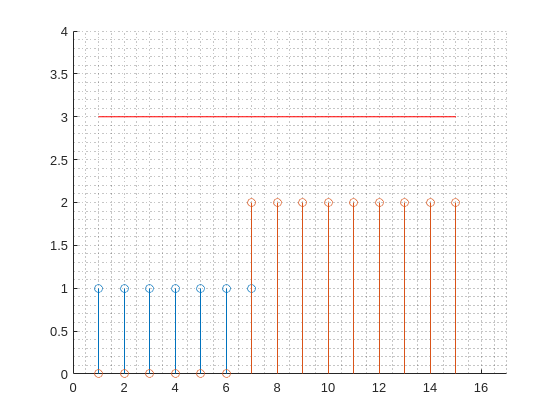


figure; hold on; stem(ks); stem(ls*2); plot([1 len],[3 3],'r'); hold off;
ylim([0,4]); xlim([0,len+2]); grid minor;

## Question 3

**a) Find a pair of sequences **$\left\lbrace a_n \right\rbrace$** and **$\left\lbrace b_n \right\rbrace$**, where each one contains at least three different values and where the convolution **$\left\lbrace a_n \right\rbrace \ast \left\lbrace b_n \right\rbrace$** results in the all-zero sequence ...,0,0,0,....**

**b) Let T be an LTI system with an impulse response that is not the all-zero sequence. Does every such T have a corresponding inverse LTI system **$T^{-1}$** such that **$\left\lbrace x_n \right\rbrace =T^{-1} T\left\lbrace x_n \right\rbrace$** for all sequences **$\left\lbrace x_n \right\rbrace$**? Why or why not?**

## Question 4

**a) Which of 16kHz, 32kHz, 48kHz would be suitable for distinguishing two whistle tones of 23kHz, 25kHz?**

Only 32kHz could distinguish these.

Given a sample frequency $f_s$, you can reconstruct a signal with frequencies between $\frac{n*f_s }{2}<|f|<\frac{\left(n+1\right)*f_s }{2}$ for a specific $n$.

To distinguish the signals, this range must include 23kHz and 25kHz:

$f_S =16\mathrm{kHz}:0-8;\;8-16;\;16-24;\;24-32\ldotp \ldotp \ldotp$ (no range with 23 and 25)

$f_S =48\mathrm{kHz}:0-24;\;24-48\ldotp \ldotp \ldotp$ (no range with 23 and 25)

$f_S =32\mathrm{kHz}:0-16;\;16-32$ (has a range with 23 and 25 for $n=1$)

**b) For each of the two whistles: for which k will **$|X_k |$**show a peak?**

Each whistle emits a sine tone => when one whistle blows, $x=\sin \left(2\pi \mathrm{ft}\right)$

When sampling, $x_i =\sin \left(\frac{2\pi \mathrm{fi}}{f_s }\right)=\sin \left(2\pi f*\frac{i}{n}*\frac{n}{f_s }\right)$

FFT peaks when this aligns with $e^{-2\pi j\;\frac{\mathrm{ik}}{n}}$=>


$$\begin{array}{l}
2\pi \frac{i}{n}k=2\pi f*\frac{i}{n}*\frac{n}{f_s }\\
k=\frac{f*n}{f_s }
\end{array}$$


($\left.f_s =160\mathrm{kHz}\right)$

Therefore for $f=23\mathrm{kHz},k=\frac{23*512}{160}=73\ldotp 6\;\left(\mathrm{rounds}\;\mathrm{to}\;74\right)$. (this doesn't align with an FFT bucket perfectly => will scallop)

For $f=25\mathrm{kHz},k=\frac{25*512}{160}=80$.

**c) Which tones will cause a higher peak in the FFT result, and why?**

As mentioned, the 23kHz signal does not align with an FFT bucket. This means it will not peak sharply on one bucket, but will scallop - the peak will spread to the buckets around the middle.

25kHz does align with an FFT bucket, so that peak will be higher than the scalloped 23kHz.

Proof:

f_s = 160E3;
f1 = 23E3;
f2 = 25E3;
block_size = 512;
blocks_per_s = f_s / block_size;
t_per_block = block_size / f_s;

t = (1/f_s):(1/f_s):t_per_block;
sampled_signal = sin(2*pi*f1*t) + sin(2*pi*f2*t);

% Adapted from https://uk.mathworks.com/help/matlab/ref/fft.html
% Compute the two-sided spectrum P2, with a hamming window.
% Then compute the single-sided spectrum P1 based on P2 and the even-valued signal length L.
Y=fft(sampled_signal .* hamming(block_size)');
L=block_size;
P2 = abs(Y/L); % Normalize impact of FFT length
% P2 is two-sided eg. includes negative frequencies
% but P2 is also symmetric
% => one-sided version is 2*(first half of P2)
P1 = P2(1:L/2);
P1(2:end) = 2*P1(2:end);

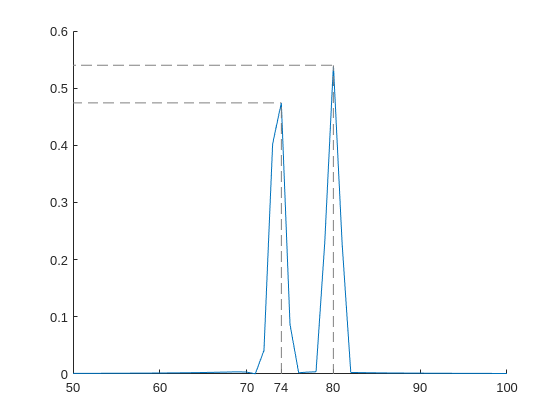

figure;
hold on;
plot(0:1:(L/2-1), P1);
% Plot lines at expected peaks
% MATLAB vectors are one-indexed, so the indices are 75 and 81
% y axis
plot([0,74],[P1(75),P1(75)],'--',"color",[0,0,0]+0.5);
plot([0,80],[P1(81),P1(81)],'--',"color",[0,0,0]+0.5);
% x axis
plot([74,74],[0,P1(75)],'--',"color",[0,0,0]+0.5);
plot([80,80],[0,P1(81)],'--',"color",[0,0,0]+0.5);
% Limit to interesting part of graph
xlim([50 100]);
xticks([50 60 70 74 80 90 100]);
title("Unfiltered FFT result - Unequal Peak Heights");
hold off;

**d) What additional linear processing step can you apply, and where, to reduce the relative amplitude difference between 23kHz and 25kHz?**

Apply a linear "4-point moving average" filter to the FFT result.

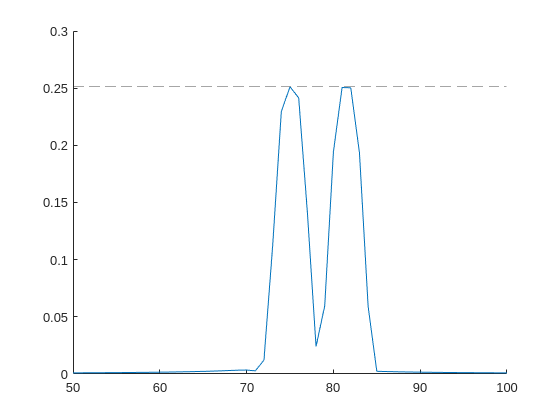

b=[1 1 1 1]/4;
a=[1];
P1_smoothed = filter(b, a, P1);

figure;
hold on;
plot(0:1:(L/2-1), P1_smoothed);
% The peaks won't be at exactly 74 or 80 now, though
yline(max(P1_smoothed),'--',"","color",[0,0,0]+0.5);
% Limit to interesting part of graph
xlim([50 100]);
title("Filtered FFT result - Equal Peak Heights");
hold off;

**e) Give an example of a second-order peak filter, operating at **$f_s$**=160kHz with pass frequency f=25kHz, in terms of the position of poles and zeros in the z-transform of its impulse response, providing an expression for H(z)**

**TODO**

## Question 5

## Question 6